# Texture analysis

This tutorial explains how to compute texture features from en-face maps.

This en-face maps can be extracted from both thickness and reflectance data. 

Tutorial steps:

- Load an OCT volume.

- Create a en-face thickness map.

- Compute texture features (fractal dimension, GLCM, LBP).

If you need help please reach out at **dromero@mondragon.edu**

close all;clc;clearvars;
addpath(genpath('../src'));

### Load a file

This step parses the information inside the file and computes the X, Y coordinates of each A-scan.

To analyse retinal thickness we only need the header and the segmentation data.

file = '../src/data/raster.vol';
[header, seg, ~, ~] = read_vol(file, 'get_coordinates');

    {'ILM'}    {'BM'}    {'RNFL_GCL'}    {'GCL_IPL'}    {'IPL_INL'}    {'INL_OPL'}    {'OPL_ONL'}    {'ELM'}    {'MZ_EZ'}    {'OSP_IZ'}    {'IZ_RPE'}




X = header.X_oct;
Y = header.Y_oct;

### **Compute thickness map**

We can now compute thicknesses as the difference between segmented boundaries.

We need to specify the layers to analyse as input.

Thickness values are by defaul in pixels, but can be computed in $\mu m$ if we pass the axial resolution (`scale_z`) to the function.

The output are stored in the struct `Thickness` with a field for every layer.

layers = {'TRT'};
Thickness = compute_thickness(seg, layers, header.scale_z);

TRT = Thickness.TRT;
[X_new, Y_new, TRT_new] = resample_map(X, Y, TRT, 'regular', 'max_d', 3, 'n_point', 100);

We can visualize the maps as

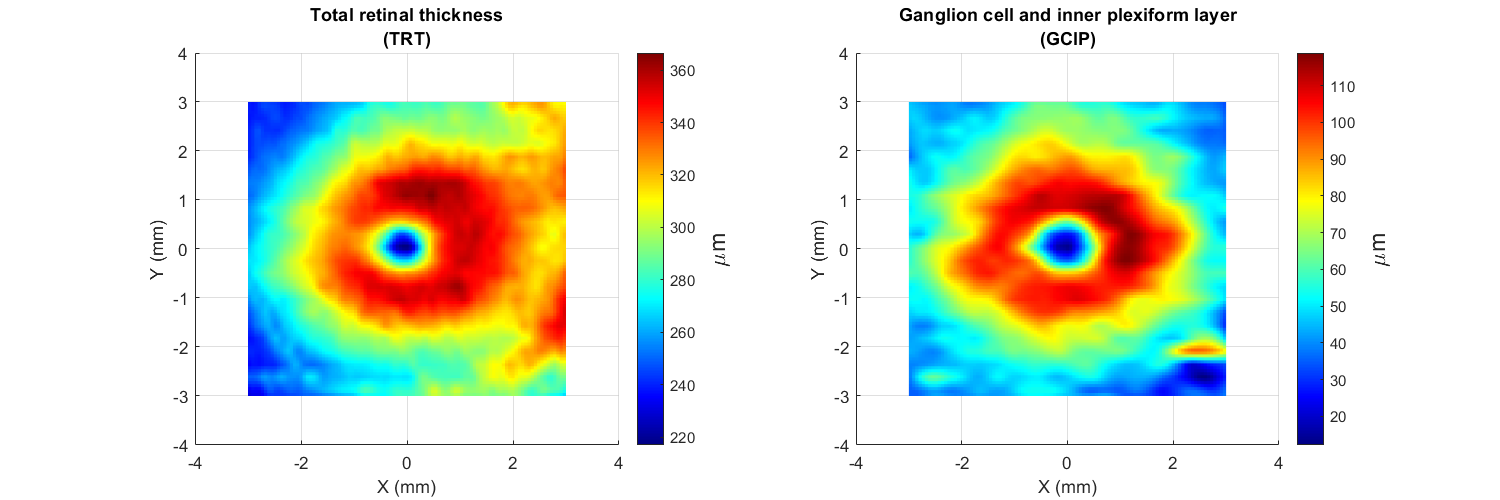

f = figure('Position', [0 0 1200 400]);
subplot(122); 
surf(X_new, Y_new, TRT_new, 'EdgeColor', 'none'); view(0, 90); 

xlabel('X (mm)'); ylabel('Y (mm)'); title({'Total retinal thickness','(TRT)'});
axis(4 * [-1 1 -1 1]);
cb = colorbar; 
cb.Label.String = '\mum';
cb.Label.FontSize = 14;

subplot(122);
surf(X_new, Y_new, TRT_new, 'EdgeColor', 'none')

colormap(jet);

### Foveal location

Often, acquired images may not be correctly centered at the foveal pit (due to fixation errors).

This can result in erroneous measurement and must be corrected. To do this we need to:

- Locate the actual foveal center automatically

- Set X, Y coordinate origin to the foveal center

[x_fovea, y_fovea] = find_fovea(X, Y, 'TRT');

X = X - x_fovea;
Y = Y - y_fovea;

## **Feature extraction**

### **Fractal analysis**

### **Gray-level co-ocurrence matrix (GLCM)**

Haralick features

### Linear binary patterns (LBP)